# Powertrain Experiments

- variable step, auto, max=10, min=.01, tol=1e-4

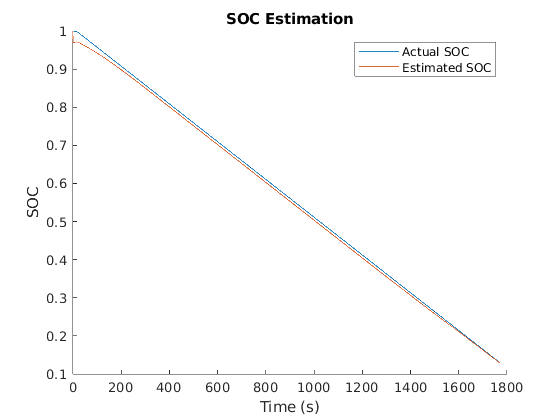

f1 = figure(1); clf;
hold on;
plot(out.soc.Time, out.soc.Data);
plot(out.soc_hat.Time, out.soc_hat.Data);
title("SOC Estimation");
legend(["Actual SOC", "Estimated SOC"]);
ylabel("SOC");
xlabel("Time (s)");
hold off;

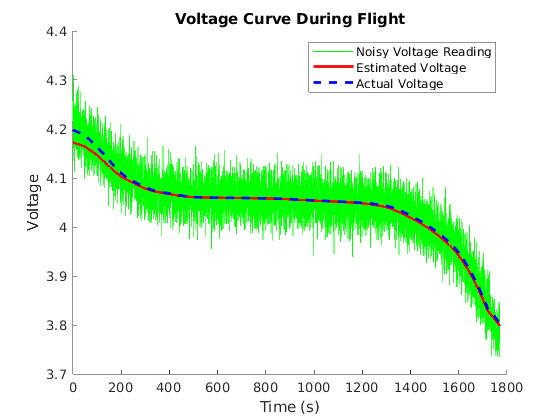

f2 = figure(2); clf;
hold on;
plot(out.noisy_v.Time, out.noisy_v.Data, 'g');
plot(out.v_batt_hat.Time, smoothdata(out.v_batt_hat.Data, 'movmean', 500), 'r', 'linewidth', 2);
plot(out.v_batt.Time, smoothdata(out.v_batt.Data, 'movmean', 500), 'b--', 'linewidth', 2);
hold off;
title("Voltage Curve During Flight");
xlabel("Time (s)");
ylabel("Voltage");
legend(["Noisy Voltage Reading", "Estimated Voltage", "Actual Voltage"]);

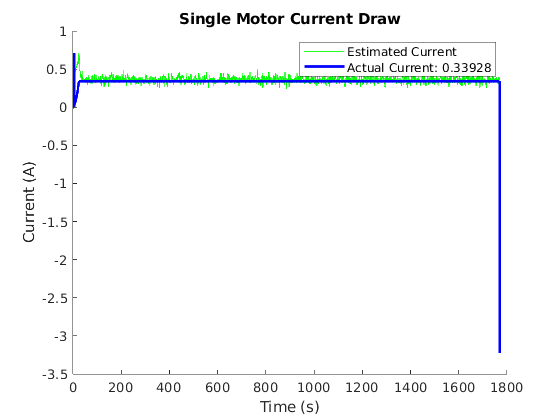

i_hatData = out.i_hat.Data(1,:);
f3 = figure(3); clf;
hold on;
plot(out.i_hat.Time, i_hatData, 'g');
plot(out.i_mot.Time, out.i_mot.Data, 'b', 'linewidth', 2);
hold off;
title("Single Motor Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Estimated Current", "Actual Current: " + num2str(out.i_mot.Data(3000))]);

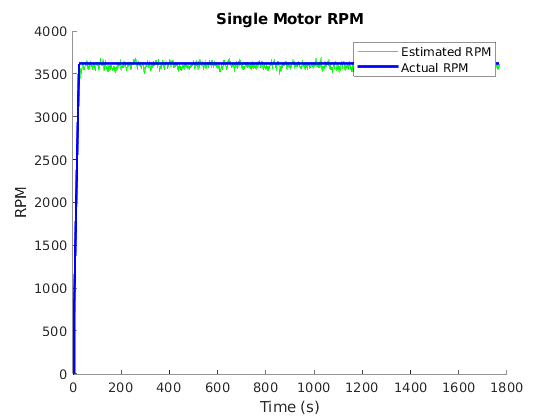

f4 = figure(4); clf;
hold on;
plot(out.rpm_hat.Time, out.rpm_hat.Data, 'g');
plot(out.rpm.Time, out.rpm.Data, 'b', 'linewidth', 2);
hold off;
xlabel("Time (s)");
ylabel("RPM");
title("Single Motor RPM");
legend(["Estimated RPM", "Actual RPM"]);

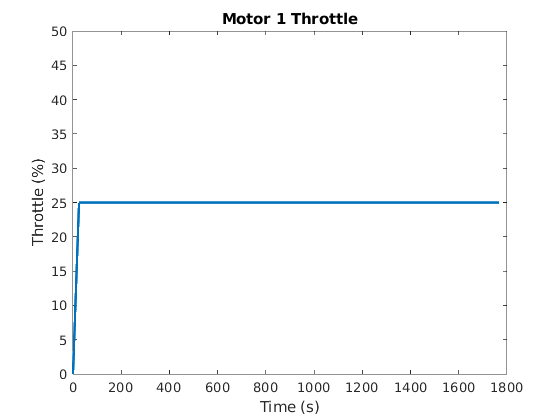

f5 = figure(5); clf;
plot(out.m1_throttle.Time, out.m1_throttle.Data, 'linewidth', 2);
title("Motor 1 Throttle");
xlabel("Time (s)");
ylabel("Throttle (%)");
ylim([0 50]);

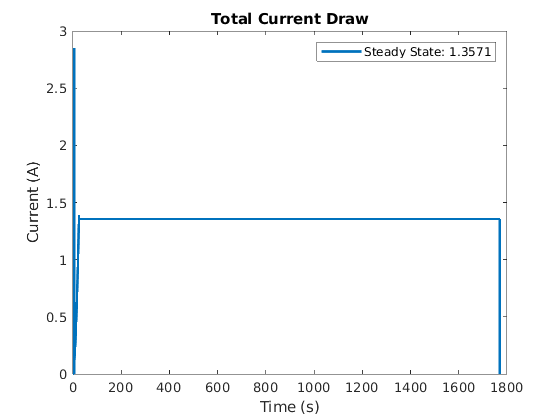

f6 = figure(6); clf;
plot(out.i_batt.Time, out.i_batt.Data, 'linewidth', 2);
title("Total Current Draw");
xlabel("Time (s)");
ylabel("Current (A)");
legend(["Steady State: " + num2str(out.i_batt.Data(3000))]);